## Principal Components of a Data Set

Load the sample data set. 

load hald

The ingredients data has 13 observations for 4 variables. 

Find the principal components for the ingredients data. 

[coeff,score,latent,tsquared,explained] = pca(ingredients);

Principal Component Coefficients (Loadings)

coeff

coeff =    -0.0678   -0.6460    0.5673    0.5062
   -0.6785   -0.0200   -0.5440    0.4933
    0.0290    0.7553    0.4036    0.5156
    0.7309   -0.1085   -0.4684    0.4844


The rows of `coeff` contain the coefficients for the four ingredient variables, and its columns correspond to four principal components. 

Principal Component Scores

score

score =    36.8218   -6.8709   -4.5909    0.3967
   29.6073    4.6109   -2.2476   -0.3958
  -12.9818   -4.2049    0.9022   -1.1261
   23.7147   -6.6341    1.8547   -0.3786
   -0.5532   -4.4617   -6.0874    0.1424
  -10.8125   -3.6466    0.9130   -0.1350
  -32.5882    8.9798   -1.6063    0.0818
   22.6064   10.7259    3.2365    0.3243
   -9.2626    8.9854   -0.0169   -0.5437
   -3.2840  -14.1573    7.0465    0.3405


Principal Component Variances

latent

latent =   517.7969
   67.4964
   12.4054
    0.2372


The values in `latent` tell you how much of the total variance in the data is explained by each principal component. Larger values indicate that the component explains a larger portion of the variance in the data.

Hotelling’s T-squared Statistic

tsquared =     5.6803
    3.0758
    6.0002
    2.6198
    3.3681
    0.5668
    3.4818
    3.9794
    2.6086
    7.4818


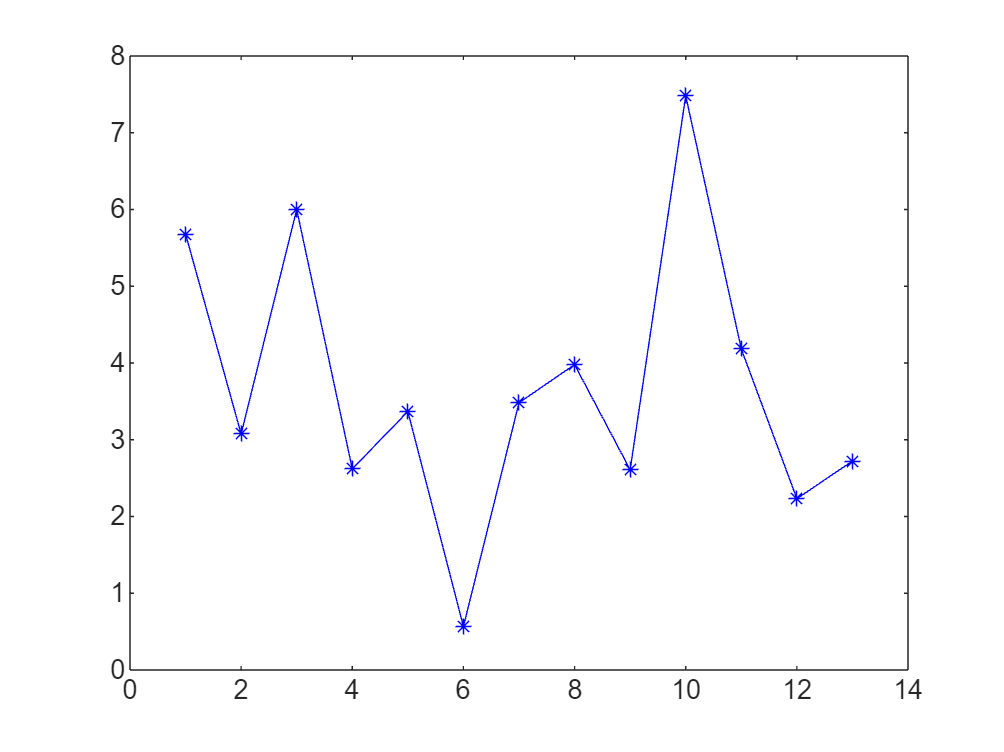

tsquared

High values in `tsquared` suggest that the corresponding observation is an outlier or is far from the center of the principal component space.

Percentage of Variance Explained

explained

explained =    86.5974
   11.2882
    2.0747
    0.0397


The values in `explained` sum to 100% and indicate how much of the total variance in the data is captured by each principal component. The first few components usually capture the majority of the variance, which is why PCA is useful for dimensionality reduction.